# Gera coeficientes aerodinâmicos para a análise do Aibrake

referência: gera_coef.m endereço: Ita Rocket Design/Mecânica de voo/RDX/AED/AED-TO-MVO

clear all
clc
close all

## Dados do foguete Montenegro 1

dref = 0.1524;
L = 2.352;
Alt0 = 1401;
Lcgf =  1.531;

## Entradas para a análise MVO

% vetor de PHI que entra como "alternativa ao angulo BETA"
% obs* no codigo do peixoto a configuracao eh phi+Alpha_Total
% ao inves de "alpha+beta". Se quiserem mudar isso, mexer no simulink.
dados.phif = 0;

dados.cg = Lcgf;

dados.alpha = [-2, 0, 2];
dados.mach  = [0.1, 0.2, 0.5, 0.6, 0.7, 0.8, 0.95, 1, 1.05, 1.1];

dados.empena = 160/1000; % Tamanho da empena

## Dados aibrake

Aqui inseriremos a modelagem do Airbrake. Para isso utilizaremos o card PROTUB de protuberâncias do DATCOM. Por default ele nos dá algumas possibilidades de protuberâncias. Nas análises iniciais, utilizaremos o airbrake do tipo BLOCK, que faz uma protuberância retangular no foguete. Para mais informações sobre esse card, consultar a página 30 do manual do DATCOM (versão 2011).

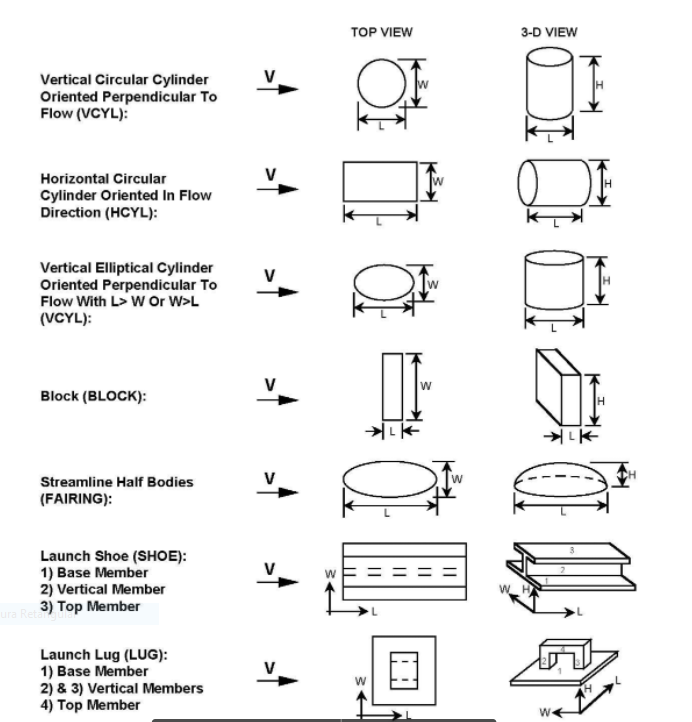

dados.hasAirbrake = 1;
dados.nBrakes = 4;
dados.positionBrakes = 1.458;
dados.lBrakes = 0.005;
dados.wBrakes = 0.068122172;
dados.hBrakes = 0.0442;

## Criando for005 com o inputs_for005_RDX2021_func para o foguete com airbrake

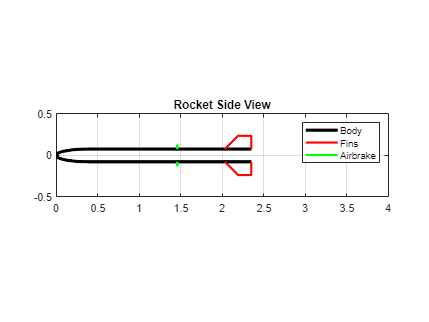

%% Inputs do for005 para foguete 2021/RDX em função de (dref,L,Alt0)
[for005] = inputs_for005_RDX2021_func(dref,L,Alt0,dados);

## Rodando o DATCOM para o caso com airbrake

tic
[M_airbrake]=DATCOM_TO_MVO_RDX2021(dados,for005);
tempo_airbrake = toc;
time = datestr(clock,'YYYY_mm_dd');
save(strcat('AIRBRAKE_',time),'M_airbrake','dados','for005')

## Rodando o DATCOM para o caso sem airbrake para comparações

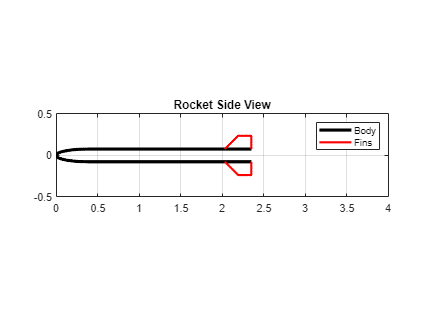

dados.hasAirbrake = 0;
[for005] = inputs_for005_RDX2021_func(dref,L,Alt0,dados);

tic
[M]=DATCOM_TO_MVO_RDX2021(dados,for005);
tempo = toc;
time = datestr(clock,'YYYY_mm_dd');
save(strcat('NO_AIRBRAKE_',time),'M','dados','for005')

## Tempo de execução

fprintf("Tempo de execução (airbrake): %.2f", tempo_airbrake);

Tempo de execução (airbrake): 0.34

%fprintf("Tempo de execução (sem airbrake): %.2f", tempo);

## Comparações